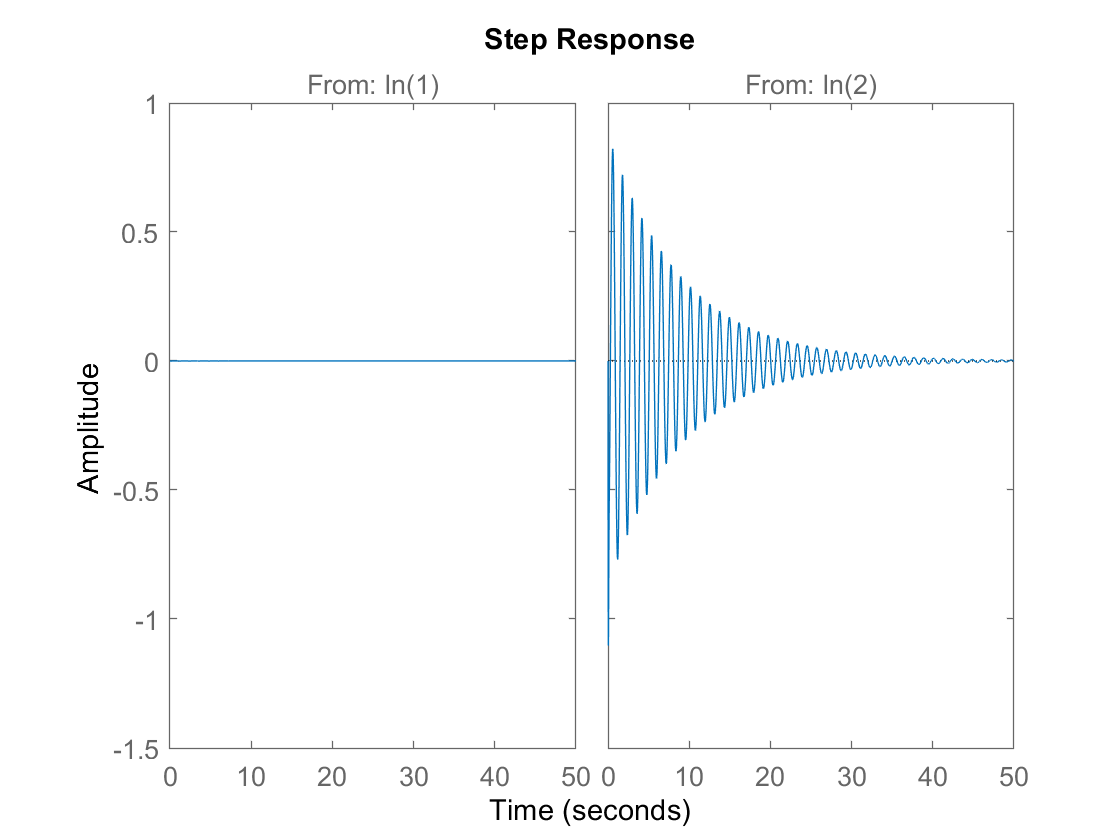

% source: http://ctms.engin.umich.edu/CTMS/index.php?example=Suspension&section=ControlStateSpace
% source: https://pdfs.semanticscholar.org/249a/26b6cf5336f5b42a1797d44aadb49360d41d.pdf

%{
(M1)    1/4 bus body mass                        2500 kg
(M2)    suspension mass                          320 kg
(K1)    spring constant of suspension system     80,000 N/m
(K2)    spring constant of wheel and tire        500,000 N/m
(b1)    damping constant of suspension system    350 N.s/m
(b2)    damping constant of wheel and tire       15,020 N.s/m
(U)     control force
%}

m1 = 2500;
m2 = 320;
k1 = 80000;
k2 = 500000;
b1 = 350;
b2 = 15020;

A=[0                 1   0                                              0
  -(b1*b2)/(m1*m2)   0   ((b1/m1)*((b1/m1)+(b1/m2)+(b2/m2)))-(k1/m1)   -(b1/m1)
   b2/m2             0  -((b1/m1)+(b1/m2)+(b2/m2))                      1
   k2/m2             0  -((k1/m1)+(k1/m2)+(k2/m2))                      0];
B=[0                 0
   1/m1              (b1*b2)/(m1*m2)
   0                -(b2/m2)
   (1/m1)+(1/m2)    -(k2/m2)];
C=[0 0 1 0];
D=[0 0];

sys=ss(A,B,C,D);

step(sys)